## POSTLAB #3 MATLAB CODE  AUTHOR: TOMOKI KOIKE

clear all; close all; clc;

% Loading the excel file
fpart1 = readmatrix("expr_part1.xlsx");
fpart2_1 = readmatrix("expr_part2.xlsx");
fpart2_2 = readmatrix('expr_part2extra.xlsx');
fpart3 = readmatrix("expr_part3.xlsx");


## 1.

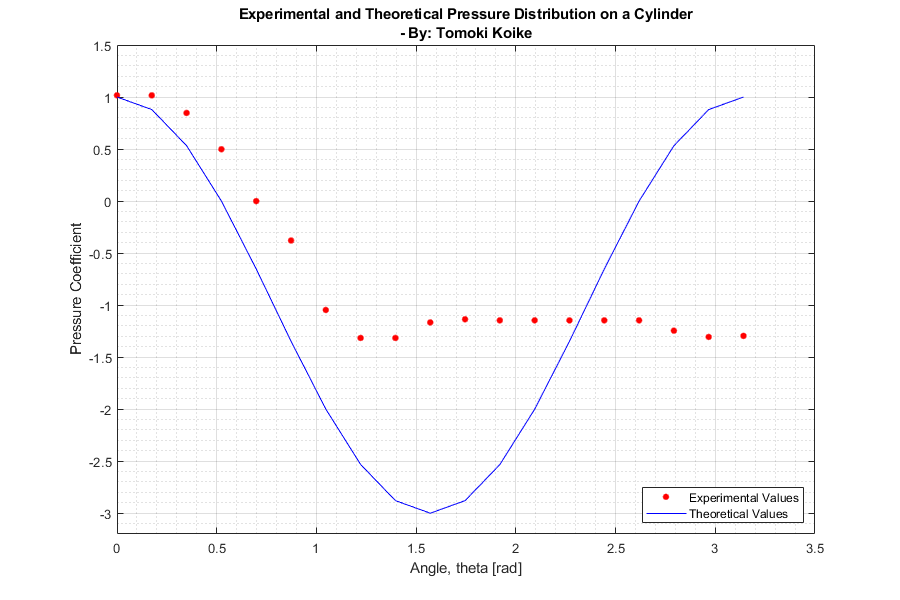

% Assigning columns of the read file to variables
cp_expr = fpart1(:,10);  % Experimental pressure ceofficients
cp_th = fpart1(:,11);  % Theoretical pressure coefficients 
theta = fpart1(:,5);  % Angle values [rad]

% Plotting
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(theta, cp_expr, '.r', 'MarkerSize', 15)
xlabel('Angle, theta [rad]')
ylabel('Pressure Coefficient')
title({'Experimental and Theoretical Pressure Distribution on a Cylinder', ['- ' ...
    'By: Tomoki Koike']})
hold on 
plot(theta, cp_th, '-b')
hold off
ylim([-3.2 1.5])
grid on
grid minor
box on
legend('Experimental Values', 'Theoretical Values', 'Location', 'southeast')

## 2a.

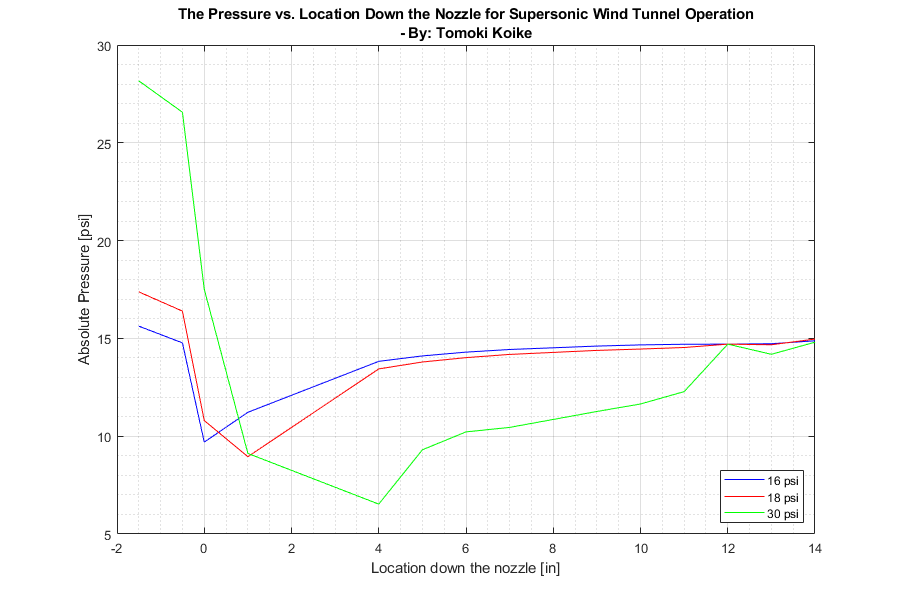

% Assigning columns or rows of the read files to variables
% Pressures are in gauage so should be converted to absolute pressure
avgP_16 = (fliplr((fpart2_1(17,3:16))))' + 14.7;  % The average pressure distribution for 16 psi
avgP_18 = (fliplr((fpart2_1(42,3:16))))' + 14.7;  % The average pressure distribution for 18 psi
avgP_30 = (fliplr((fpart2_1(57,3:16))))' + 14.7;  % The average pressure distribution for 30 psi
tapPos = fpart2_2(:,1);  % The tap positions [in]
tapPos = tapPos(1:length(avgP_16));

% Plotting
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(tapPos, avgP_16, '-b')
xlabel('Location down the nozzle [in]')
ylabel('Absolute Pressure [psi]')
title({['The Pressure vs. Location Down the Nozzle for Supersonic Wind Tunnel ' ...
    'Operation'], '- By: Tomoki Koike'})
hold on 
plot(tapPos, avgP_18, '-r')
plot(tapPos, avgP_30, '-g')
hold off
grid on
grid minor 
box on
legend('16 psi', '18 psi', '30 psi', 'Location', 'southeast')

## 2b.

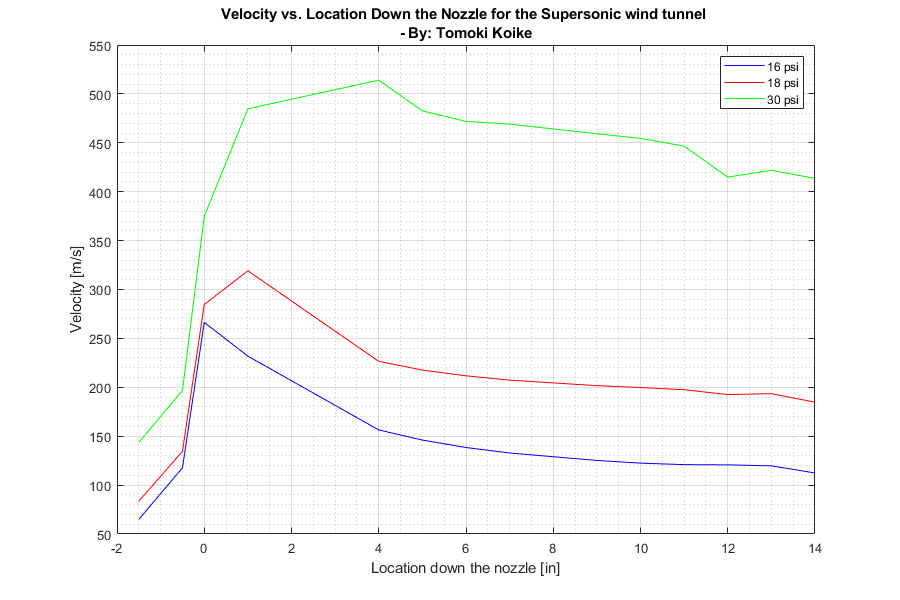

% Defining constants
rho = 1.225;  % Density of air [kg/m^3]
g = 9.81;  % Gravitational acceleration [m/s^2]

% Assigning from read file
h = fpart2_2(:,2);  % Heights from base to nozzle [in]
h = h(1:length(avgP_16));

% Converting data from imperial to metric
avgP_16 = avgP_16 * 6894.757;  % psi to Pa
avgP_18 = avgP_18 * 6894.757;
avgP_30 = avgP_30 * 6894.757;
h = h * 0.0254;  % in to m
p16 = 16 * 6894.757;  % 16 psi to Pa
p18 = 18 * 6894.757;  % 18 psi to Pa
p30 = 30 * 6894.757;  % 30 psi to Pa

% Calculating the velocity
v16 = sqrt(2*(p16 - avgP_16 + rho*g.*h)./rho);  % Velocity for Po=16psi
v18 = sqrt(2*(p18 - avgP_18 + rho*g.*h)./rho);  % Velocity for Po=18psi
v30 = sqrt(2*(p30 - avgP_30 + rho*g.*h)./rho);  % Velocity for Po=30psi

% Plotting 
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(tapPos, v16, '-b')
xlabel('Location down the nozzle [in]')
ylabel('Velocity [m/s]')
title({['Velocity vs. Location Down the Nozzle for the Supersonic wind ' ...
    'tunnel '], '- By: Tomoki Koike'})
hold on
plot(tapPos, v18, '-r')
plot(tapPos, v30, '-g')
hold off
grid on
grid minor
box on
legend('16 psi', '18 psi', '30 psi')

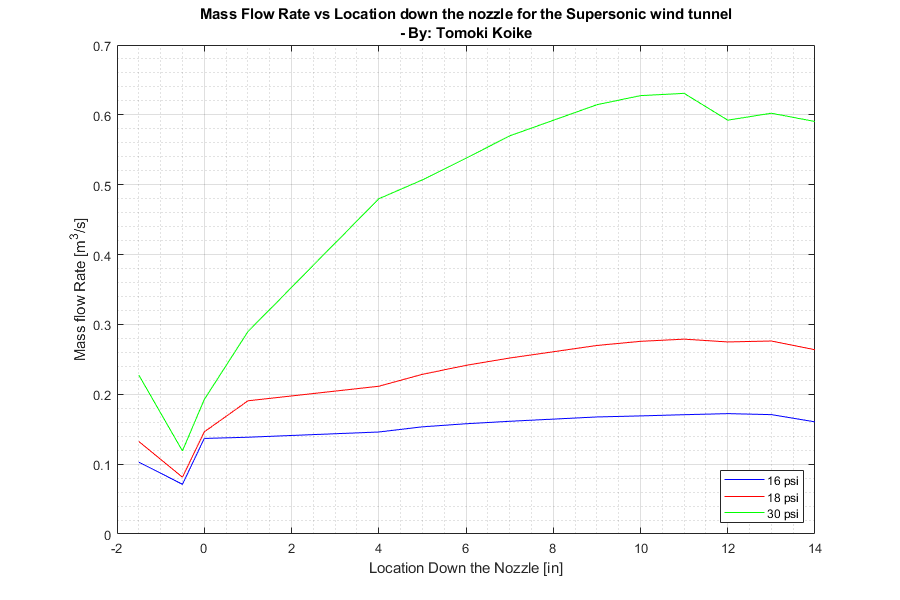


% Checking with mass flow rate
A = fpart2_2(:,3);  % Assigning the area values to column vector [m^2]
A = A(1:length(avgP_16));
mfr16 = A.*v16;  % Mass flow rate for 16psi
mfr18 = A.*v18;  % Mass flow rate for 18psi
mfr30 = A.*v30;  % Mass flow rate for 30psi

%Plotting
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(tapPos, mfr16, '-b')
xlabel('Location Down the Nozzle [in]')
ylabel('Mass flow Rate [m^3/s]')
title({['Mass Flow Rate vs Location down the nozzle for the Supersonic wind' ...
    ' tunnel'], '- By: Tomoki Koike'})
hold on
plot(tapPos, mfr18, '-r')
plot(tapPos, mfr30, '-g')
hold off
grid on
grid minor
box on
legend('16 psi', '18 psi', '30 psi', 'Location', 'southeast')

## 2c.

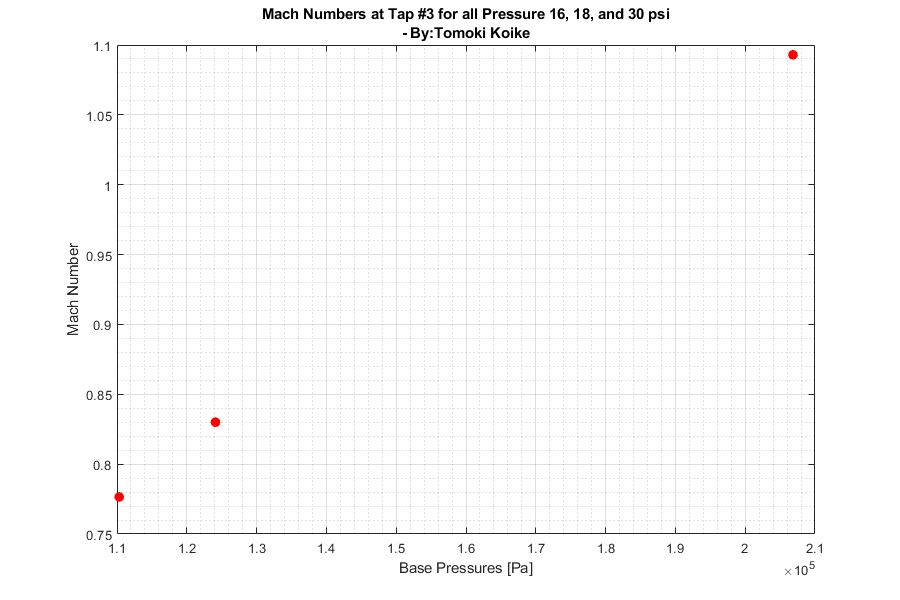

% A vector with the base pressure 
ps = [p16 p18 p30];
% A vector with mach numbers at tap 3 for corresponding base pressures
machs = [v16(3)/343 v18(3)/343 v30(3)/343];

%Plotting
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(ps, machs, '.r', 'MarkerSize', 25)
xlabel('Base Pressures [Pa]')
ylabel('Mach Number')
title({'Mach Numbers at Tap #3 for all Pressure 16, 18, and 30 psi', ['- By:' ...
    'Tomoki Koike']})
grid on
grid minor
box on

## Error Analysis

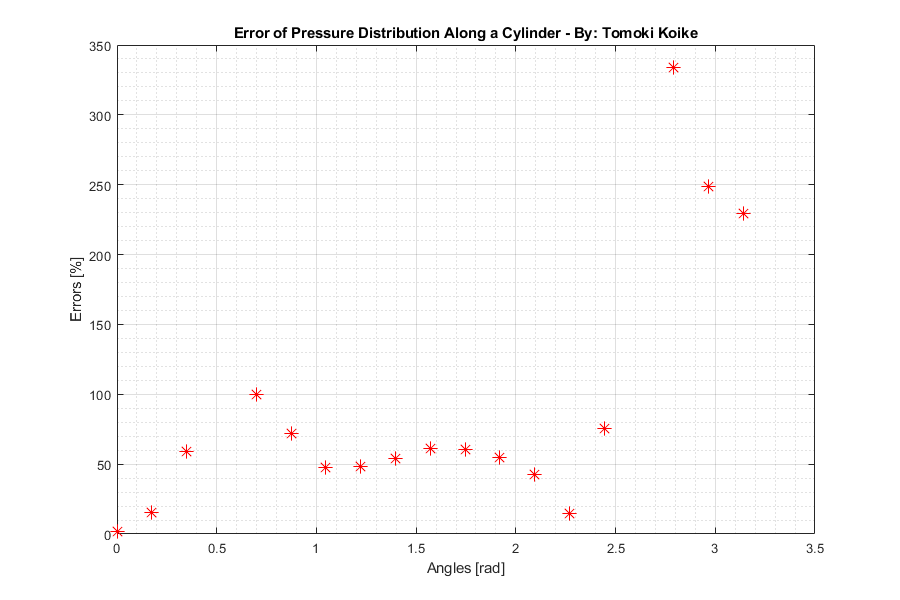

errs = fpart1(:,12);  % The column vector for error values

%Plotting
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(theta, errs, '*r', 'MarkerSize', 10)
xlabel('Angles [rad]')
ylabel('Errors [%]')
title({'Error of Pressure Distribution Along a Cylinder - By: Tomoki Koike'})
grid on
grid minor
box on